% Read the image
img = imread("running.PNG");

% Convert the image to double type
img = im2double(img);

% Perform tone mapping using the Reinhard algorithm
img_tone_mapped = tonemap(img,'AdjustLightness', [.05 1], 'AdjustSaturation', 1);

Creating an hdr image from 6 different expsure levels

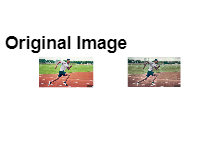

image2= imread("exposure\image (1).png");
image3= imread("exposure\image (2).png");
image4= imread('exposure\image (3).png');
image5=imread("exposure\image (4).png");
image6=imread("exposure\image (5).png");
image1=imread("exposure\image.png");
images={image1,image2,image3,image4,image5,image6};
montage(images)
exposure = [0.0333 0.1000 0.3333 0.5250 1,5];
relExposure = exposure./exposure(1);
hdr = makehdr(images,'RelativeExposure',relExposure);
rgb = tonemap(hdr);
imshow(rgb)

Reinhard algorithm is not the only kind of tonemapper there exists ACES using the localtonemap() function this uses the ACES filmic renderer.

% Display the original and tone mapped images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_tone_mapped);
title('Tone Mapped Image');